clear
clf
clc
load("RandomVariableLab_Data.mat")

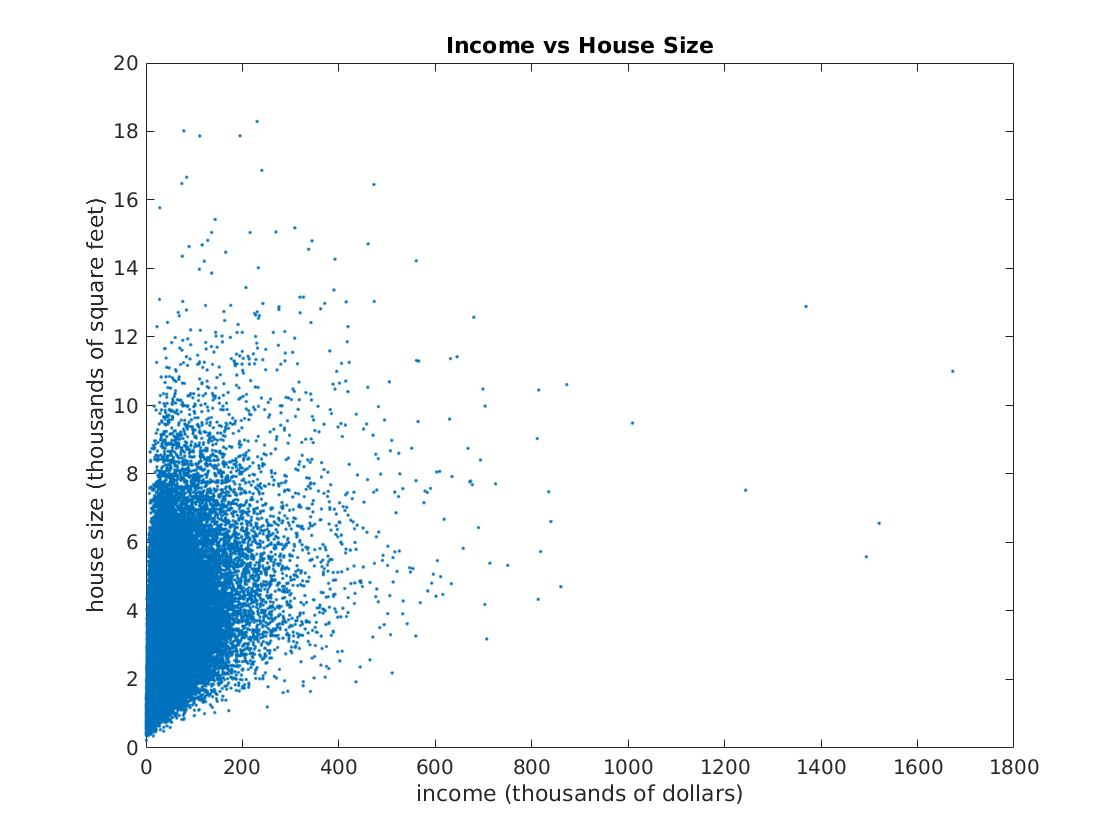

%step2
clf
plot(X/1000,Y/1000,'.')
xlabel('income (thousands of dollars)')
ylabel('house size (thousands of square feet)')
title('Income vs House Size')

`Most people have low income and small houses but there are outliers on the upper ends of both metrics.`

`Income has a greater spread than house size with more extreme outliers.`

%step 3
mean1 = mean(X);
mean2 = mean(Y);
m = [mean1; mean2]

m = 	1.0e+04 *

    3.6546
    0.2777


std1 = std(X);
std2 = std(Y);
covXY = mean((X-mean1).*(Y-mean2));
C = [std1^2 covXY;covXY std2^2]

C = 	1.0e+09 *

    2.2409    0.0357
    0.0357    0.0022


%compare with matlab's function
cov(X,Y)

ans = 	1.0e+09 *

    2.2409    0.0357
    0.0357    0.0022


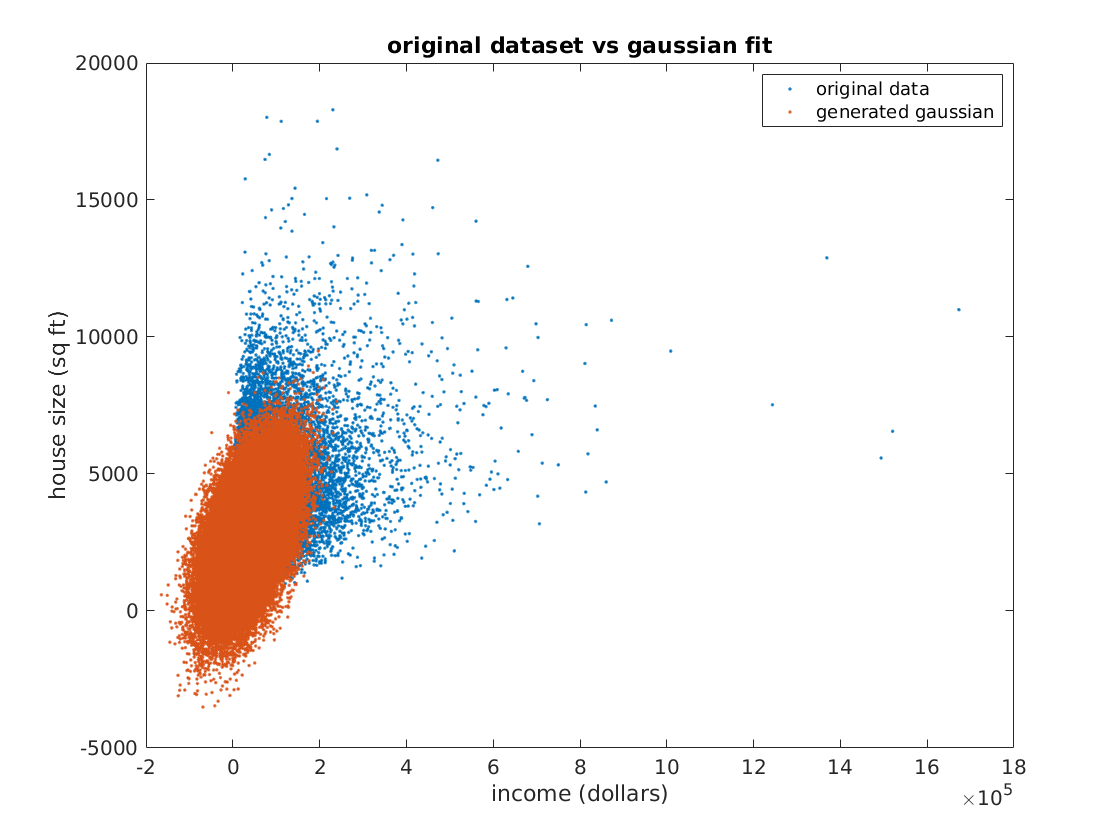

%step 4
clf
generatedNormal = mvnrnd(m,C,100000);
plot(X,Y,'.')
hold on
plot(generatedNormal(:,1),generatedNormal(:,2),'.')
legend('original data','generated gaussian')
xlabel('income (dollars)')
ylabel('house size (sq ft)')
title('original dataset vs gaussian fit')

The gaussian distribution is not a good fit. Visually, the plots do not overlap well. The original data has a wedge shape while the gaussian generated data has an ellipsoid shape.

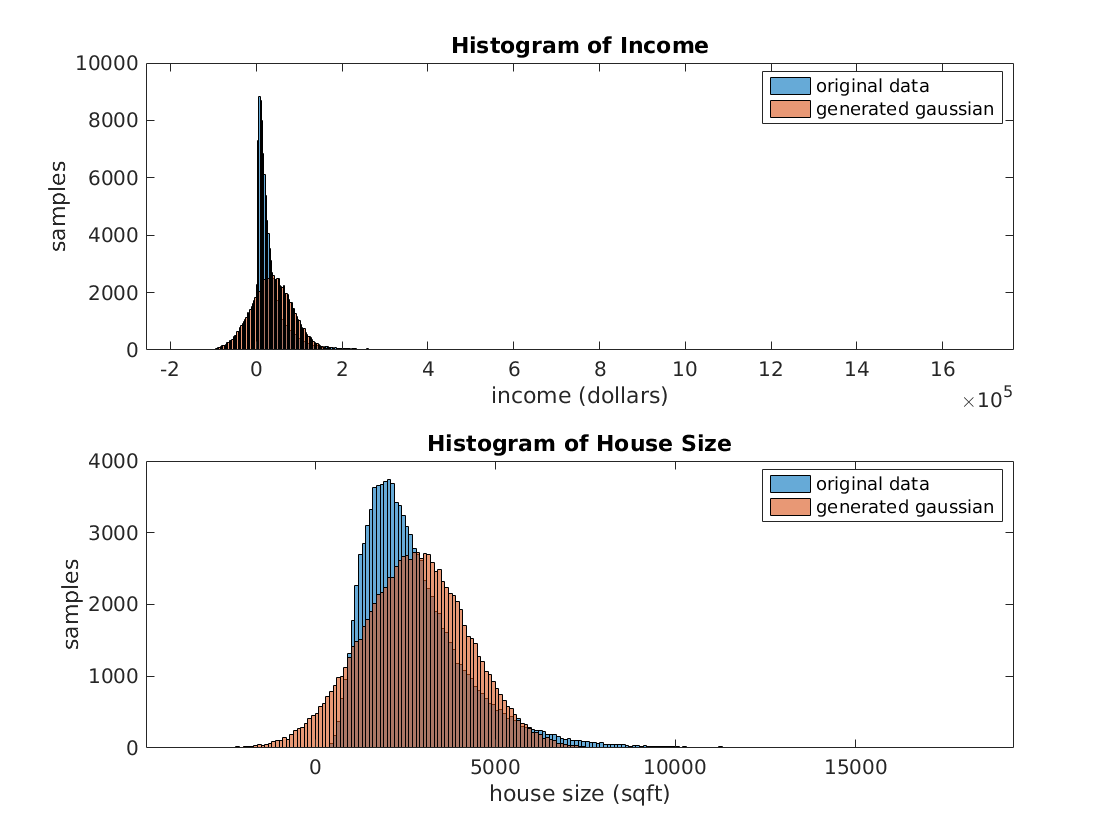

%step 5
clf
subplot(2,1,1)
histogram(X)
hold on
histogram(generatedNormal(:,1))
title('Histogram of Income')
xlabel('income (dollars)')
ylabel('samples')
legend('original data','generated gaussian')
subplot(2,1,2)
histogram(Y)
hold on
histogram(generatedNormal(:,2))
title('Histogram of House Size')
xlabel('house size (sqft)')
ylabel('samples')
legend('original data','generated gaussian')

Neither of these distributions appear gaussian because they skew right

%step 6
lnx = log(X);
lny = log(Y);

lnm = [mean(lnx);mean(lny)]

lnm =    10.0053
    7.8038


lnc = cov(lnx,lny)

lnc =     1.0037    0.3026
    0.3026    0.2503



m1 = lnm(1)

m1 = 10.0053

m2 = lnm(2)

m2 = 7.8038

sigma1 = sqrt(lnc(1,1))

sigma1 = 1.0018

sigma2 = sqrt(lnc(2,2))

sigma2 = 0.5003

rho = lnc(1,2)/sigma1/sigma2

rho = 0.6037

%step 7
clf
lngaussian = mvnrnd(lnm,lnc,100000)

lngaussian =    10.5260    7.7731
   11.5010    7.7251
    8.2328    7.0726
   11.7585    8.2026
   10.8580    8.7113
    9.8985    7.7492
   10.7634    7.7730
   10.9736    7.9718
   10.1864    7.4842
   10.5706    8.4246


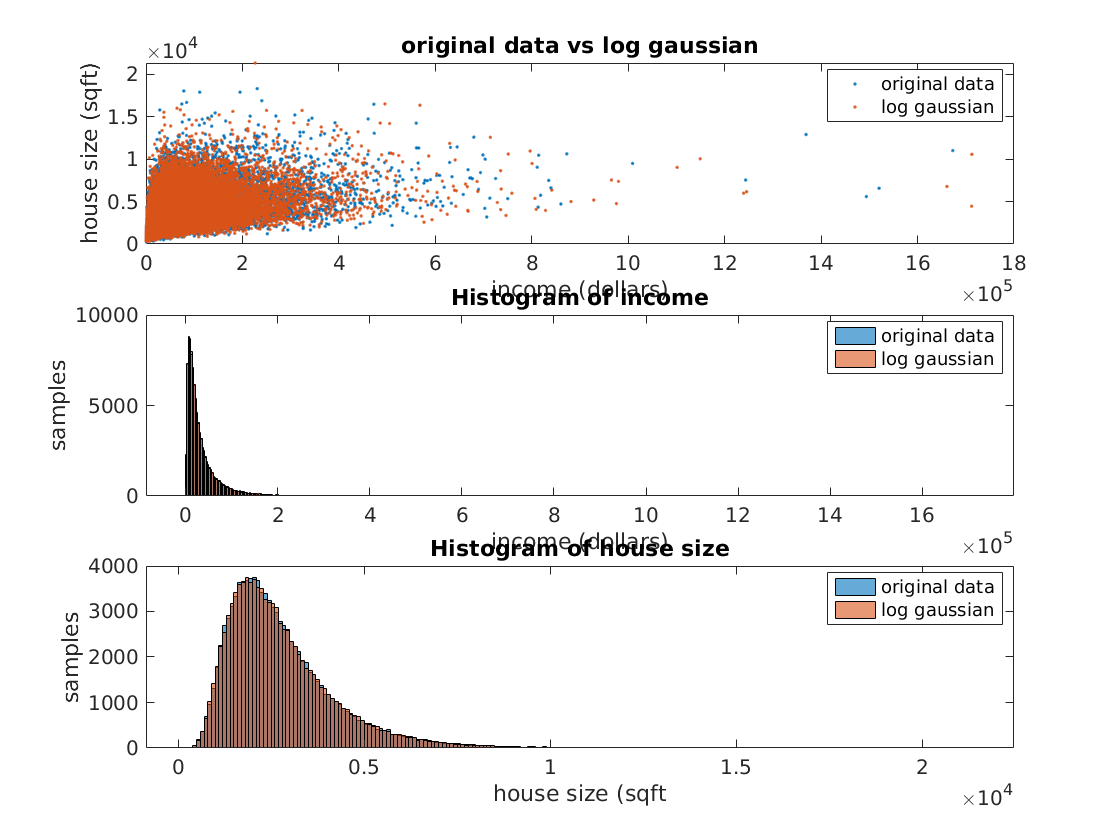

subplot(3,1,1)
plot(X,Y,'.')
hold on
plot(exp(lngaussian(:,1)),exp(lngaussian(:,2)),'.')

xlabel('income (dollars)')
ylabel('house size (sqft)')
title('original data vs log gaussian')
legend('original data','log gaussian')

subplot(3,1,2)
histogram(X)
hold on
histogram(exp(lngaussian(:,1)))

title('Histogram of income')
xlabel('income (dollars)')
ylabel('samples')
legend('original data','log gaussian')

subplot(3,1,3)
histogram(Y)
hold on
histogram(exp(lngaussian(:,2)))
title('Histogram of house size')
xlabel('house size (sqft')
ylabel('samples')
legend('original data','log gaussian')

This distribution is a much better fit for the data. The histogram distributions almost completely overlap and the multivariate distribution has the same shape.

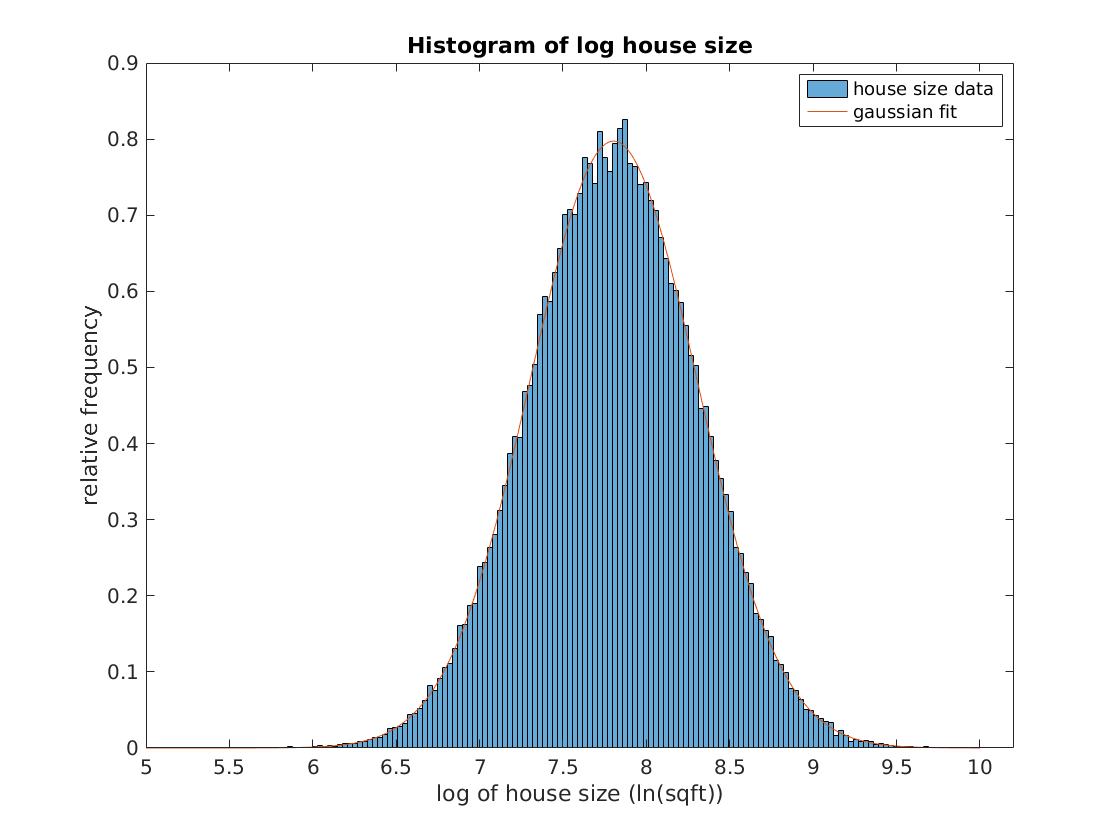

%step 8
clf
lnhousesizes =  5:0.01:10;
housesizepdf = normpdf(lnhousesizes,m2,sigma2);
histogram(lngaussian(:,2),'Normalization',"pdf")
hold on
plot(lnhousesizes,housesizepdf)
title('Histogram of log house size')
xlabel('log of house size (ln(sqft))')
ylabel('relative frequency')
legend('house size data','gaussian fit')

%step 9
incomesorted = sort(X);
jeffBezos = incomesorted(99001:end);
onepercent = sum(jeffBezos)/sum(incomesorted)*100

onepercent = 9.0624

gincomesorted = sort(generatedNormal(:,1));
elonMusk = gincomesorted(99001:end);
gonepercent= sum(elonMusk)/sum(gincomesorted)*100

gonepercent = 4.4551

In the sampled population, the top one percent owns 9.06 percent of the total wealth of the sample.

In a society where wealth were distributed according to a gaussian with same mean and variance, the top one percent would own 4.44 percent of the total wealth.